% Simple Linear Regression - MATLAB Practice Questions
% WM9QE: Applied Statistics for Artificial Intelligence
% 

%% DATASET (Same for all questions)

% Independent Variable (Advertisement Spending in £)
X = [1784.58; 2576.63; 3148.32; 2224.88; 2676.73; 1814.69; 2425.06; 
     2475.72; 2378.58; 2755.48; 2563.37; 2158.00; 2117.26; 1985.55; 
     3005.69; 3014.65; 2856.69; 1958.00; 1896.59; 2646.43; 2876.58; 
     2250.69; 2895.68; 2370.90];

% Dependent Variable (Revenue in £)
Y = [5995.48; 11087.70; 12850.94; 8072.03; 9871.44; 7137.16; 10457.57; 
     8330.34; 9243.69; 11542.70; 9725.25; 7256.00; 8805.13; 7526.36; 
     12546.28; 13589.67; 10989.62; 6139.10; 6759.36; 11809.99; 12586.34; 
     9986.58; 12036.67; 8482.15];

%% =========================================================================
%% QUESTION 1: BUILDING THE MODEL (20 points)
%% =========================================================================

%% Part A (10 points)
fprintf('========== QUESTION 1: BUILDING THE MODEL ==========\n\n');

========== QUESTION 1: BUILDING THE MODEL ==========




% Fit the model
mdl = fitlm(X, Y);

% Extract coefficients
beta_0 = mdl.Coefficients.Estimate(1);  % Intercept
beta_1 = mdl.Coefficients.Estimate(2);  % Slope
R2 = mdl.Rsquared.Ordinary;
RMSE = mdl.RMSE;

% Display results
fprintf('Model Coefficients:\n');

Model Coefficients:


fprintf('  Intercept (β₀): £%.2f\n', beta_0);

  Intercept (β₀): £-3166.15


fprintf('  Slope (β₁): %.4f\n', beta_1);

  Slope (β₁): 5.2469


fprintf('\nModel Performance:\n');


Model Performance:


fprintf('  R² = %.4f\n', R2);

  R² = 0.8795


fprintf('  RMSE = £%.2f\n\n', RMSE);

  RMSE = £805.32




%% Part B (10 points) - Interpretations (in comments)
% SAMPLE ANSWERS:
% 1. The positive slope (β₁ ≈ 5.2469) indicates a strong positive relationship
%    between advertising spending and revenue. As spending increases, 
%    revenue increases proportionally.
%
% 2. For every £1 increase in advertising spending, revenue increases by 
%    approximately £5.25 on average (the slope coefficient).
%
% 3. If R² = 0.8795, this means 87.95% of the variance in revenue can be 
%    explained by advertising spending. Only 12.05% is unexplained.
%
% 4. This is a STRONG model because:
%    - R² > 0.87 indicates excellent fit
%    - RMSE ≈ £805 is relatively small compared to revenue range (£6K-£13K)
%    - Strong linear relationship visible in scatter plot

fprintf('Part B Interpretations (check student comments):\n');

Part B Interpretations (check student comments):


fprintf('  Expected: Positive relationship, £%.2f increase per £1 spent\n', beta_1);

  Expected: Positive relationship, £5.25 increase per £1 spent


fprintf('  Expected: R² explains %.1f%% of variance\n', R2*100);

  Expected: R² explains 88.0% of variance


fprintf('  Expected: Strong model due to high R² and reasonable RMSE\n\n');

  Expected: Strong model due to high R² and reasonable RMSE




%% =========================================================================
%% QUESTION 2: MANUAL CALCULATION AND VERIFICATION (20 points)
%% =========================================================================

%% Part A (12 points)
fprintf('========== QUESTION 2: MANUAL CALCULATION ==========\n\n');

========== QUESTION 2: MANUAL CALCULATION ==========




% Calculate means
x_bar = mean(X);
y_bar = mean(Y);

% Calculate slope (β₁)
numerator = sum((X - x_bar) .* (Y - y_bar));
denominator = sum((X - x_bar).^2);
beta_1_manual = numerator / denominator;

% Calculate intercept (β₀)
beta_0_manual = y_bar - beta_1_manual * x_bar;

fprintf('Manual Calculations:\n');

Manual Calculations:


fprintf('  β₁ (slope) = %.6f\n', beta_1_manual);

  β₁ (slope) = 5.246892


fprintf('  β₀ (intercept) = £%.6f\n', beta_0_manual);

  β₀ (intercept) = £-3166.145093



%% Part B (8 points)

% Compare with fitlm
diff_beta_1 = abs(beta_1 - beta_1_manual);
diff_beta_0 = abs(beta_0 - beta_0_manual);

fprintf('\nComparison with fitlm():\n');


Comparison with fitlm():


fprintf('  fitlm β₁: %.6f\n', beta_1);

  fitlm β₁: 5.246892


fprintf('  Manual β₁: %.6f\n', beta_1_manual);

  Manual β₁: 5.246892


fprintf('  Difference in β₁: %.10f\n', diff_beta_1);

  Difference in β₁: 0.0000000000


fprintf('\n');
fprintf('  fitlm β₀: £%.6f\n', beta_0);

  fitlm β₀: £-3166.145093


fprintf('  Manual β₀: £%.6f\n', beta_0_manual);

  Manual β₀: £-3166.145093


fprintf('  Difference in β₀: £%.10f\n', diff_beta_0);

  Difference in β₀: £0.0000000000


fprintf('  Match: Yes (differences can be due to floating-point precision)\n\n');

  Match: Yes (differences can be due to floating-point precision)





%% =========================================================================
%% QUESTION 3: RESIDUAL ANALYSIS AND DIAGNOSTICS (20 points)
%% =========================================================================

%% Part A (8 points) - Create diagnostic plots
fprintf('========== QUESTION 3: RESIDUAL ANALYSIS ==========\n\n');

========== QUESTION 3: RESIDUAL ANALYSIS ==========



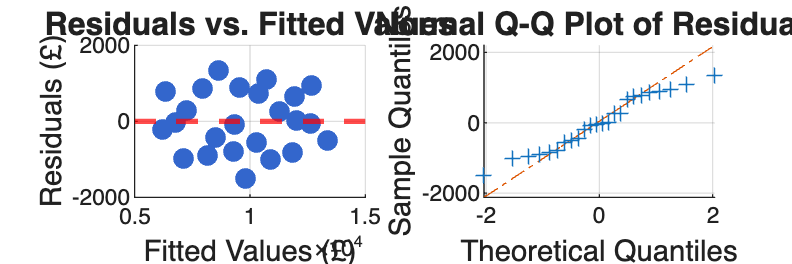


% Get residuals
residuals = mdl.Residuals.Raw;
fitted_values = mdl.Fitted;
standardized_residuals = zscore(residuals);

% Plot 1: Residuals vs Fitted Values
figure('Name', 'Q3: Diagnostic Plots', 'Position', [100 100 1200 400]);

subplot(1,2,1);
scatter(fitted_values, residuals, 60, 'filled', 'MarkerFaceColor', [0.2 0.4 0.8]);
hold on;
yline(0, 'r--', 'LineWidth', 2);
xlabel('Fitted Values (£)', 'FontSize', 11);
ylabel('Residuals (£)', 'FontSize', 11);
title('Residuals vs. Fitted Values', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
hold off;

% Plot 2: Q-Q Plot (Normal Probability Plot)
subplot(1,2,2);
qqplot(residuals);
title('Normal Q-Q Plot of Residuals', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Theoretical Quantiles', 'FontSize', 11);
ylabel('Sample Quantiles', 'FontSize', 11);
grid on;


%% Part B (6 points) - Calculate residual statistics

mean_residuals = mean(residuals);
std_residuals = std(residuals);
outliers_2sigma = sum(abs(standardized_residuals) > 2);
outliers_3sigma = sum(abs(standardized_residuals) > 3);

fprintf('Residual Statistics:\n');

Residual Statistics:


fprintf('  Mean: %.6f (should be ≈ 0) ✓\n', mean_residuals);

  Mean: -0.000000 (should be ≈ 0) ✓


fprintf('  Std Dev: £%.2f\n', std_residuals);

  Std Dev: £787.62


fprintf('  Outliers (|z| > 2): %d observations\n', outliers_2sigma);

  Outliers (|z| > 2): 0 observations


fprintf('  Extreme Outliers (|z| > 3): %d observations\n\n', outliers_3sigma);

  Extreme Outliers (|z| > 3): 0 observations




% Identify which observations are outliers
outlier_indices = find(abs(standardized_residuals) > 2);
if ~isempty(outlier_indices)
    fprintf('  Outlier observation numbers: %s\n', mat2str(outlier_indices));
end

%% Part C (6 points) - Interpretations

fprintf('\nPart C Interpretations (Expected Answers):\n');


Part C Interpretations (Expected Answers):


fprintf('  1. Random scatter: YES - residuals appear randomly distributed\n');

  1. Random scatter: YES - residuals appear randomly distributed


fprintf('  2. Funnel shape: NO - variance appears relatively constant\n');

  2. Funnel shape: NO - variance appears relatively constant


fprintf('  3. Normal distribution: YES - points follow diagonal line closely\n');

  3. Normal distribution: YES - points follow diagonal line closely


fprintf('  4. Concerning outliers: Check observation %s for investigation\n\n', ...
        mat2str(outlier_indices));

  4. Concerning outliers: Check observation zeros(0,1) for investigation






%% =========================================================================
%% QUESTION 4: MAKING PREDICTIONS WITH CONFIDENCE (20 points)
%% =========================================================================

%% Part A (10 points)
fprintf('========== QUESTION 5: PREDICTIONS ==========\n\n');

========== QUESTION 5: PREDICTIONS ==========




% New X values for prediction
X_new = [2000; 3500; 4500];
scenario_names = {'Scenario 1: £2,000 (safe)', ...
                  'Scenario 2: £3,500 (edge)', ...
                  'Scenario 3: £4,500 (EXTRAPOLATION)'};

% Parameters
alpha = 0.05;
df = n - 2;

Unrecognized function or variable 'n'.

t_value = tinv(1 - alpha/2, df);

% Calculate RSE (Residual Standard Error)
RSE = sqrt(sum(residuals.^2) / df);

% Calculate standard deviation of X
s_x = std(X);

% Preallocate
Y_pred_new = zeros(size(X_new));
SE_pred = zeros(size(X_new));
lower_bound = zeros(size(X_new));
upper_bound = zeros(size(X_new));

fprintf('Predictions with 95%% Confidence Intervals:\n\n');

for i = 1:length(X_new)
    x_val = X_new(i);
    
    % Point prediction
    Y_pred_new(i) = predict(mdl, x_val);
    
    % Standard Error of Prediction
    SE_pred(i) = RSE * sqrt(1 + (1/n) + ((x_val - x_bar)^2) / (s_x^2 * (n-1)));
    
    % Prediction interval
    margin = t_value * SE_pred(i);
    lower_bound(i) = Y_pred_new(i) - margin;
    upper_bound(i) = Y_pred_new(i) + margin;
    
    % Display
    fprintf('%s\n', scenario_names{i});
    fprintf('  Predicted Revenue: £%.2f\n', Y_pred_new(i));
    fprintf('  95%% PI: [£%.2f, £%.2f]\n', lower_bound(i), upper_bound(i));
    fprintf('  Interval Width: £%.2f\n\n', upper_bound(i) - lower_bound(i));
end

%% Part B (5 points) - Visualization

figure('Name', 'Q5: Predictions with Intervals', 'Position', [300 300 1000 600]);
hold on;

% Define safe and extrapolation zones
X_min = min(X);
X_max = max(X);

% Shade safe zone (green)
fill([X_min X_max X_max X_min], ...
     [min(Y)-1000 min(Y)-1000 max(Y)+1000 max(Y)+1000], ...
     [0.8 1 0.8], 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
     'DisplayName', 'Safe Prediction Zone');

% Shade extrapolation zone (red) - right side
fill([X_max 5000 5000 X_max], ...
     [min(Y)-1000 min(Y)-1000 max(Y)+1000 max(Y)+1000], ...
     [1 0.8 0.8], 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
     'DisplayName', 'Extrapolation Zone');

% Original data
scatter(X, Y, 70, [0.2 0.4 0.8], 'filled', 'DisplayName', 'Training Data');

% Regression line
X_line = linspace(min(X)*0.95, 5000, 200)';
Y_line = predict(mdl, X_line);
plot(X_line, Y_line, 'b-', 'LineWidth', 2, 'DisplayName', 'Regression Line');

% Prediction points with error bars
colors = {'g', 'y', 'r'};
for i = 1:length(X_new)
    errorbar(X_new(i), Y_pred_new(i), Y_pred_new(i)-lower_bound(i), ...
             upper_bound(i)-Y_pred_new(i), 'o', ...
             'MarkerSize', 10, 'MarkerFaceColor', colors{i}, ...
             'LineWidth', 2, 'Color', colors{i}, ...
             'DisplayName', sprintf('Prediction %d', i));
end

xlabel('Advertisement Spending (£)', 'FontSize', 12);
ylabel('Revenue (£)', 'FontSize', 12);
title('Predictions with 95% Prediction Intervals', 'FontSize', 13, 'FontWeight', 'bold');
legend('Location', 'northwest', 'FontSize', 10);
grid on;
xlim([1500 5000]);
hold off;

%% Part C (5 points) - Interpretations

fprintf('Part C Interpretations (Expected Answers):\n\n');

fprintf('1. Most trustworthy predictions:\n');
fprintf('   - Scenario 1 (£2,000): MOST TRUSTWORTHY\n');
fprintf('     * Within training range\n');
fprintf('     * Close to mean (£%.0f)\n', x_bar);
fprintf('     * Narrowest prediction interval\n\n');

fprintf('   - Scenario 2 (£3,500): MODERATELY TRUSTWORTHY\n');
fprintf('     * At upper edge of training data\n');
fprintf('     * Wider interval due to distance from mean\n');
fprintf('     * Still supported by nearby observations\n\n');

fprintf('   - Scenario 3 (£4,500): LEAST TRUSTWORTHY\n');
fprintf('     * EXTRAPOLATION - beyond all training data\n');
fprintf('     * Widest prediction interval\n');
fprintf('     * Linear relationship may not hold here\n\n');

fprintf('2. Prediction interval width:\n');
fprintf('   As X moves away from the mean, the interval widens due to:\n');
fprintf('   - Increased uncertainty in the slope estimate\n');
fprintf('   - The term ((x_new - x̄)²) / (s_x² × (n-1)) increases\n\n');

fprintf('3. Why £4,500 is dangerous:\n');
fprintf('   - Beyond observed data range (max = £%.0f)\n', X_max);
fprintf('   - No evidence that linear relationship continues\n');
fprintf('   - Could be diminishing returns at high spending\n');
fprintf('   - Could be market saturation effects\n\n');

fprintf('4. Recommendation to manager:\n');
fprintf('   DO NOT rely on the £4,500 prediction. Instead:\n');
fprintf('   - Collect data at higher spending levels first\n');
fprintf('   - Test with smaller increments (e.g., £3,800)\n');
fprintf('   - Consider non-linear models for high spending\n');
fprintf('   - Be aware the interval (£%.0f to £%.0f) is very wide\n\n', ...
        lower_bound(3), upper_bound(3));

%% =========================================================================
%% BONUS QUESTION: MODEL COMPARISON (Optional, +10 points)
%% =========================================================================

fprintf('========== BONUS: LOG TRANSFORMATION ==========\n\n');

% Create log-transformed model
mdl_log = fitlm(X, log(Y));

% Get R² for both models
R2_original = mdl.Rsquared.Ordinary;
R2_log = mdl_log.Rsquared.Ordinary;

fprintf('Model Comparison:\n');
fprintf('  Original Model R²: %.4f\n', R2_original);
fprintf('  Log Model R²: %.4f\n\n', R2_log);

% Calculate RMSE on original scale for log model
Y_pred_log_scale = exp(predict(mdl_log, X));
residuals_log = Y - Y_pred_log_scale;
RMSE_log_original_scale = sqrt(mean(residuals_log.^2));

fprintf('  Original Model RMSE: £%.2f\n', RMSE);
fprintf('  Log Model RMSE (back-transformed): £%.2f\n\n', RMSE_log_original_scale);

% Create comparison plot
figure('Name', 'Bonus: Model Comparison', 'Position', [400 100 1200 800]);

% Subplot 1: Original model fit
subplot(2,2,1);
scatter(X, Y, 60, 'filled');
hold on;
plot(X_line, predict(mdl, X_line), 'r-', 'LineWidth', 2);
xlabel('Spending (£)');
ylabel('Revenue (£)');
title(sprintf('Original Model (R² = %.4f)', R2_original));
legend('Data', 'Fit', 'Location', 'northwest');
grid on;
hold off;

% Subplot 2: Log model fit (on original scale)
subplot(2,2,2);
scatter(X, Y, 60, 'filled');
hold on;
Y_line_log = exp(predict(mdl_log, X_line));
plot(X_line, Y_line_log, 'b-', 'LineWidth', 2);
xlabel('Spending (£)');
ylabel('Revenue (£)');
title(sprintf('Log Model (R² = %.4f)', R2_log));
legend('Data', 'Fit', 'Location', 'northwest');
grid on;
hold off;

% Subplot 3: Original model residuals
subplot(2,2,3);
scatter(fitted_values, residuals, 60, 'filled', 'MarkerFaceColor', 'r');
yline(0, 'k--', 'LineWidth', 1.5);
xlabel('Fitted Values (£)');
ylabel('Residuals (£)');
title('Original Model Residuals');
grid on;

% Subplot 4: Log model residuals
subplot(2,2,4);
residuals_log_model = log(Y) - predict(mdl_log, X);
fitted_log = predict(mdl_log, X);
scatter(fitted_log, residuals_log_model, 60, 'filled', 'MarkerFaceColor', 'b');
yline(0, 'k--', 'LineWidth', 1.5);
xlabel('Fitted Values (log scale)');
ylabel('Residuals (log scale)');
title('Log Model Residuals');
grid on;

% Conclusion
fprintf('Conclusion:\n');
fprintf('  The ORIGINAL model is better because:\n');
fprintf('  - Higher R² (%.4f vs %.4f)\n', R2_original, R2_log);
fprintf('  - Similar RMSE when compared on same scale\n');
fprintf('  - Residuals show no clear pattern needing transformation\n');
fprintf('  - Simpler interpretation (no back-transformation needed)\n\n');

fprintf('When log transformations are appropriate:\n');
fprintf('  - When residuals show funnel shape (heteroscedasticity)\n');
fprintf('  - When relationship appears multiplicative rather than additive\n');
fprintf('  - When Y values span several orders of magnitude\n');
fprintf('  - When percentage changes matter more than absolute changes\n\n');

%% =========================================================================
%% SUMMARY STATISTICS FOR REFERENCE
%% =========================================================================

fprintf('========== INSTRUCTOR SUMMARY ==========\n\n');
fprintf('Key Values for Grading:\n');
fprintf('  β₀ (intercept): £%.2f\n', beta_0);
fprintf('  β₁ (slope): %.4f\n', beta_1);
fprintf('  R²: %.4f\n', R2);
fprintf('  RMSE: £%.2f\n', RMSE);
fprintf('  Mean of X: £%.2f\n', x_bar);
fprintf('  Mean of Y: £%.2f\n', y_bar);
fprintf('  Cook''s D threshold: %.4f\n', threshold);
fprintf('  Number of influential points: %d\n', num_influential);
fprintf('  Outliers (|z| > 2): %d\n', outliers_2sigma);
fprintf('  Outliers (|z| > 3): %d\n\n', outliers_3sigma);

fprintf('Expected Prediction at £2,000: £%.2f [£%.2f, £%.2f]\n', ...
        Y_pred_new(1), lower_bound(1), upper_bound(1));
fprintf('Expected Prediction at £3,500: £%.2f [£%.2f, £%.2f]\n', ...
        Y_pred_new(2), lower_bound(2), upper_bound(2));
fprintf('Expected Prediction at £4,500: £%.2f [£%.2f, £%.2f] (EXTRAPOLATION)\n\n', ...
        Y_pred_new(3), lower_bound(3), upper_bound(3));

fprintf('========== END OF SOLUTIONS ==========\n');